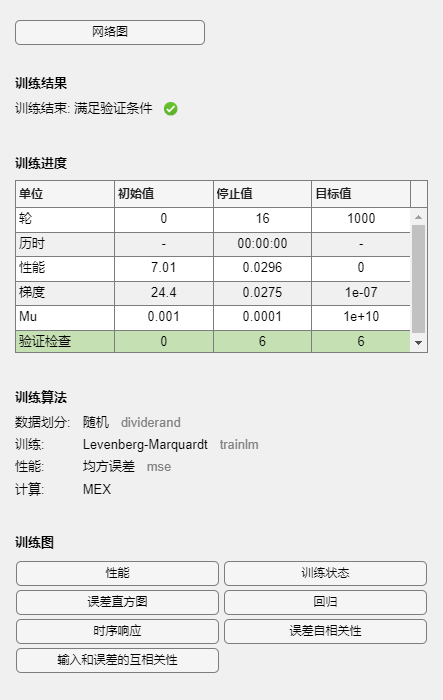

clc;
clear;
load ph_dataset.mat;

[X,T]=ph_dataset;
trainFcn='trainlm';

inputDelays=1:4;
feedbackDelays=1:4;
hiddenLayerSize=10;
net=narxnet(inputDelays,feedbackDelays,hiddenLayerSize,'open',trainFcn);

[x,xi,ai,t]=preparets(net,X,{},T);


net.divideParam.trainRatio=0.7;
net.divideParam.valRatio=0.15;
net.divideParam.testRatio=0.15;

[net,tr]=train(net,x,t,xi,ai);

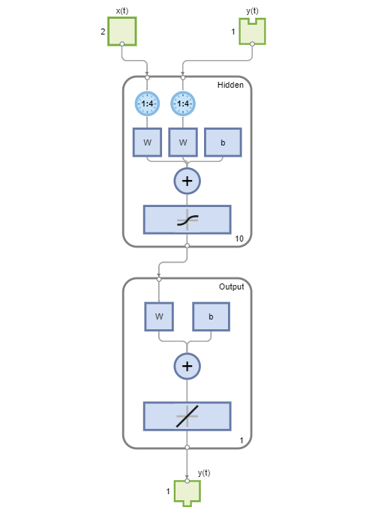


y=net(x,xi,ai);
e=gsubtract(t,y);
performance=perform(net,t,y);

view(net);

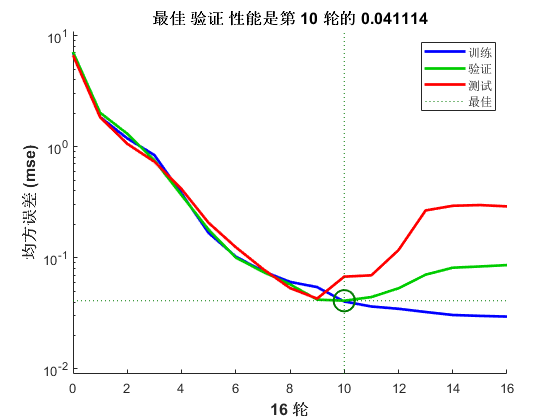

figure,plotperform(tr)

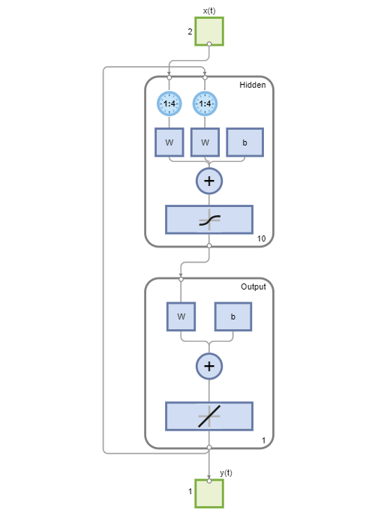

netc=closeloop(net);
netc.name=[net.name '-Closed loop'];
view(netc)

[xc,xic,aic,tc]=preparets(netc,X,{},T);
yc=netc(xc,xic,aic);
closedLoopPerformance=perform(net,tc,yc)

closedLoopPerformance =        8.7137


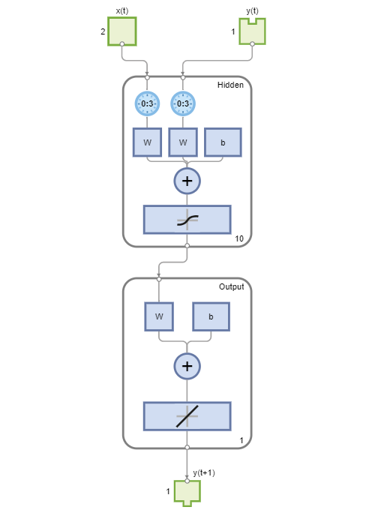

nets=removedelay(net);
nets.name=[net.name 'Predict One Step Ahead'];
view(nets)

[xs,xis,ais,ts]=preparets(nets,X,{},T);
ys=nets(xs,xis,ais);
stepAheadPerformance=perform(nets,ts,ys)

stepAheadPerformance =      0.044613
